## Wighted Hinfnorm 

The H-inf norm is tested with the weighting function W_Delta

obtain system description

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

obtain controller gain K from Design procedure 2. 

param = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0014    0.0014    0.0014    0.0082    0.1780    0.1794    0.1794    0.1820    3.0391    4.1899    4.2894    4.3188


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -5.8861   -3.7193   -0.0473  -35.3607   -4.0279   -0.0231  -39.0341   -3.9902   -0.0230  -31.9229   -3.9896   -0.0225


Eigenvalues of the coupled systems are all negative 


ans =   -90.8194  -80.2837  -62.6284  -12.0194   -3.8636   -4.0289   -3.9907   -3.9912   -0.0473   -0.0225   -0.0231   -0.0230


#### Plot and save wighted M

uses the filter specefied in equation 5.24

Mw = model.calculateMw(param); 

s =
 
  s
 
Continuous-time transfer function.
Model Properties



disp("Largest singular value |M_W|_\infty")

Largest singular value |M_W|_\infty


max(max(sigma(Mw)))

ans = 0.2282

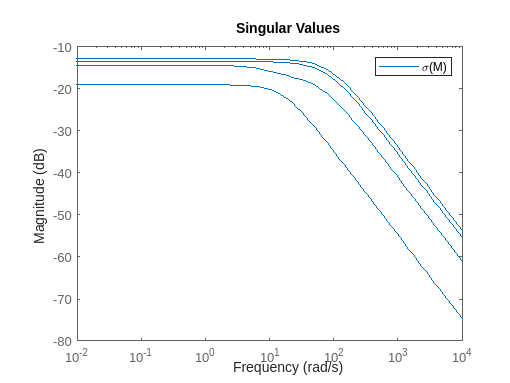

figure()
sigma(Mw)
legend("\sigma(M)")
ylabel("Magnitude")
saveas(gcf,"Images/SigamMWighted","epsc")

#### Plot and save non-wighted M

s = tf('s');

s =
 
  s
 
Continuous-time transfer function.
Model Properties



Mw = model.calculateMw((param));

s =
 
  s
 
Continuous-time transfer function.
Model Properties


disp("Largest singular value |M_W|_\infty")

Largest singular value |M_W|_\infty



max(max(sigma(Mw)))

ans = 0.2282

figure()
sigma(Mw)
ylabel("Magnitude")
legend("\sigma(M)")

saveas(gcf,"Images/SigamMNonWighted","epsc")